# Using simulink to visualise submersible system behaviour

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of more complex components and connections. In such cases writing code can be messy or difficult and it is often easier to capture the scenario using tools such as simulink.

This livescript is a brief introduction to the use of simulink to model and simulate a simple submersible system, that is an autonomous underwater vehicle. It also shows how integration with MATLAB code can make running the simulink file very efficient to allow systematic investigations for a range of parameter values. This livescript file makes use of the following simulink files:

- submersible_system_control101.slx            

- submersible_system_nonlinear_control101.slx  

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Preamble

Many simulink files have a large number of parameters which are most conveniently defined with a supporting MATLAB script and thus one might as well run the simulink file directly from the same script and produce neat plots rather than using scopes. For convenience, this resource uses a simple step input component for the input and both a scope and output blocks for the output. 

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

## 1. Simple submersible model

We consider a submersible system as shown in Figure 1.1.

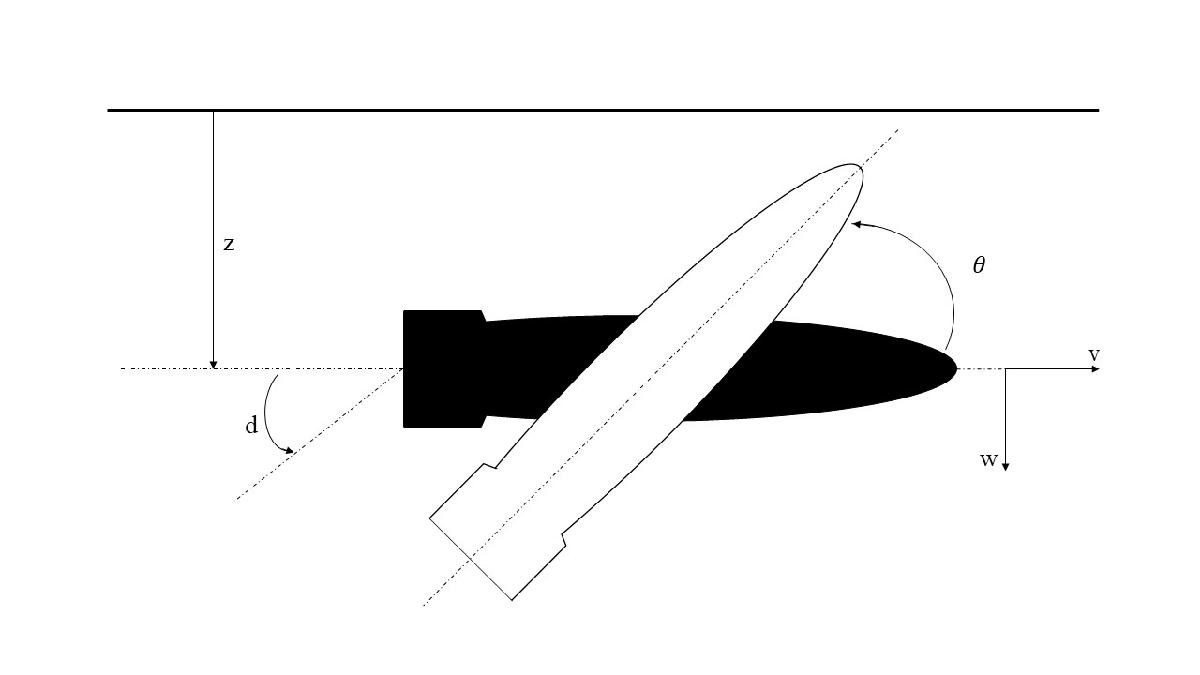

**Figure 1: **Schematic of the submersible

It is important to note that depth *z* is positive in a downwards direction and pitch angle $\theta \;$is positive in an clockwise direction (not anti-clockwise). The submersible speed in the forward direction *v* and lateral direction *w* are measured relative to the vehicle. The elevator deflection, which is the control input, is *d*. Consequently, the vehicle dynamics can be captured using the following equations.


$$\begin{array}{l}
\frac{\textrm{dw}}{\textrm{dt}}=6\ldotp 2q-1\ldotp 23w+5\ldotp 26d\\
\frac{\textrm{dq}}{\textrm{dt}}=-6\ldotp 18q+1\ldotp 68w+5\ldotp 9d\\
\frac{d\theta }{\textrm{dt}}=q\\
\frac{\textrm{dz}}{\textrm{dt}}=-w\;\cos \left(\theta \right)+v\;\sin \left(\theta \right)\;\;\;\;\left\lbrace \approx -w+v\theta ,\;\;\;\;\left|\theta \right|\le 5^o \right\rbrace 
\end{array}$$
 

A state feedback law to control the depth is given as:


$$d=z_r -k_1 \theta -k_2 z-k_3 q$$


## 2. Simulation of the submersible system model

The model equations could be put into state space form and simple tools from the control toolbox used to simulate this system. However, the purpose of this file is to explore the use of simulink as it gives transparency to the model and feedback structures as well as allowing easy monitoring of signals and the inclusion of non-linear components as required. The following 2 subsections illustrate a simulink diagram to capture and simulate the closed-loop system represented by the model in section 1.

The diagram is a little messy due to the number of states and interdependencies, but it gives clarity to those dependencies and helps viewers realise how they could engage with and code more complicated systems in the future.

### 2.1 Nominal simulation

A simple simulink component exploits Laplace Transform or transfer function models. We can express each independent differential equation in this form, for example:


$$\left\lbrace \frac{\textrm{dw}}{\textrm{dt}}=6\ldotp 2q-1\ldotp 23w+5\ldotp 26d\right\rbrace \;\to \;\left\lbrace W\left(s\right)=\frac{1}{s+1\ldotp 23}\left\lbrack 6\ldotp 2Q\left(s\right)+5\ldotp 26\;D\left(s\right)\right\rbrack \right\rbrace$$


We can use the transfer function blocks  in simulink to capture this and thus implement the full model as shown here.

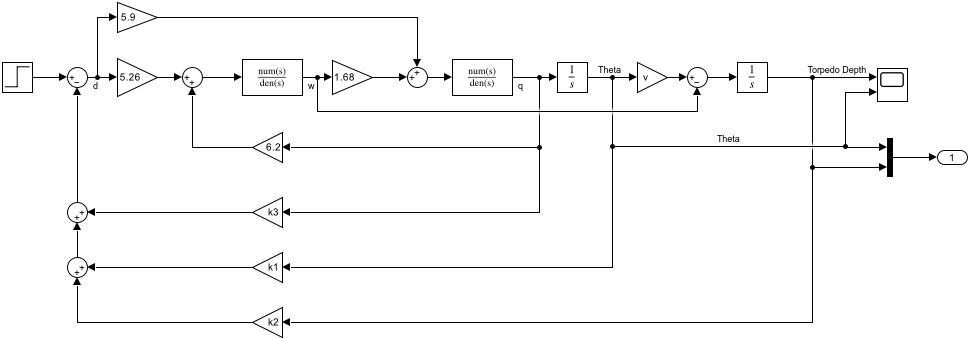

**Figure 2.1: **Simulink model for the submersible

The code below defines some suitable parameters and executes the simulation. Users can of course modify the numbers used as needed to investigate changes in speed, target depth, feedback law and more.

disp('*****************************')

*****************************


disp('Section 2.1 illustrations below')

Section 2.1 illustrations below


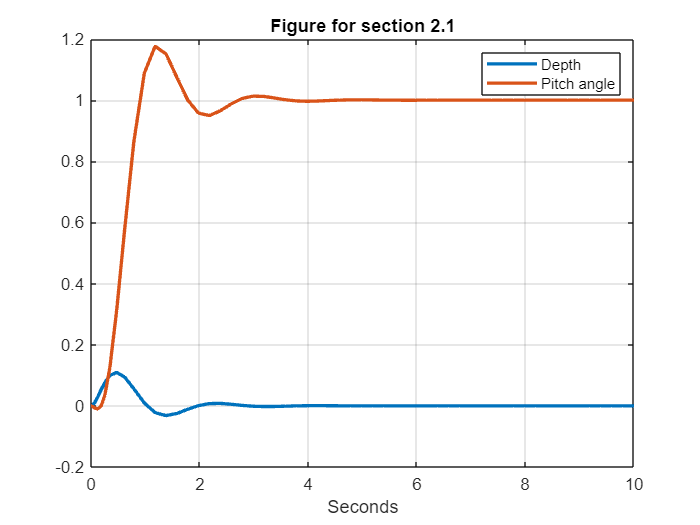


% open submersible_system_control101.slx  % to open simulink file

% Define parameters needed by simulink file - modify as needed
%v=40; k1=18; k2=0.8; k3=1.5;
v=20; k1=10; k2=1; k3=1;


% Simulation
sim("submersible_system_control101.slx");
% Output data is in the variables tout and yout

% Plotting
figure
plot(tout,yout,'LineWidth',2)
grid
legend('Depth','Pitch angle')
title('Figure for section 2.1')
xlabel('Seconds')



%print(['-ssubmersible_system_control101'],'-djpeg',['submersible_system_control101.jpg'])

### 2.2 What is the impact of using the non-linear model?

In section 1 it was proposed that for small angles the trigonometric functions are linearised. However it is interesting to investigate the immpact of this simplification and simulink provides an ideal tool for such investigations.  

The next example is somewhat messy in that it incorporates two parallel simulations in the same simulink file; this is primarily for transparency so students can see the differences clearly. The top model uses the full trigonometric functions and indeed shows how easily or transparently this can be done. The the bottom model uses a linearisation (as in section 2.1).

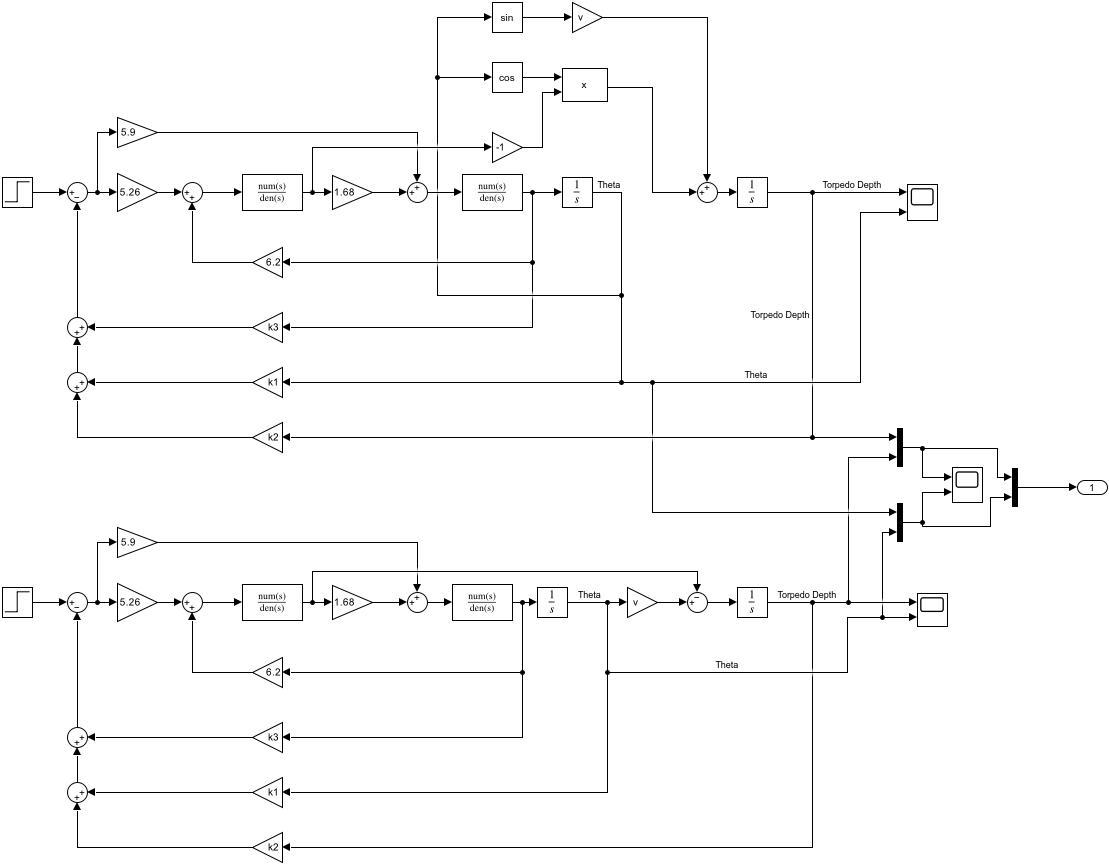

**Figure 2.2.** Linear and non-linear model in same simulink file

A simulation  below shows that the differences between the two models are indiscernible and thus, in this case, the linear model is fit for purpose.

disp('*****************************')

*****************************


disp('Section 2.2 illustrations below')

Section 2.2 illustrations below


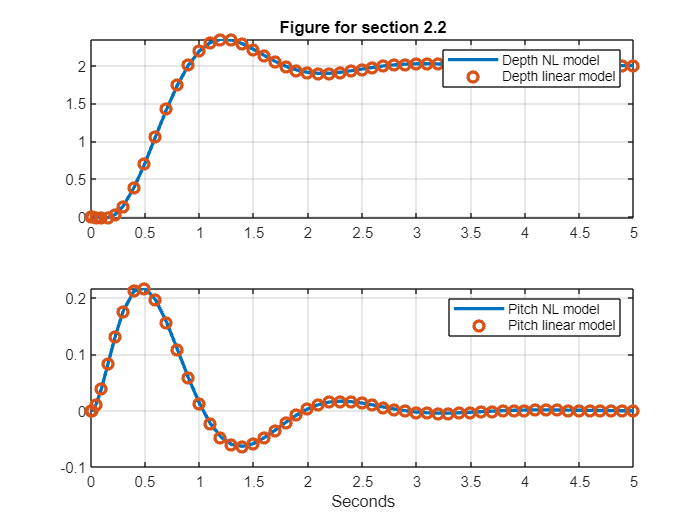


% Define parameters needed by simulink file - modify as needed
v=20; k1=10; k2=1; k3=1;

% Simulation
sim("submersible_system_nonlinear_control101.slx");
% Output data is in the variables tout and yout

% Plotting
figure
subplot(211)
plot(tout,yout(:,1),'-',tout,yout(:,2),'o','LineWidth',2)
grid
legend('Depth NL model','Depth linear model')
title('Figure for section 2.2')
subplot(212)
plot(tout,yout(:,3),'-',tout,yout(:,4),'o','LineWidth',2)
legend('Pitch NL model','Pitch linear model')
grid
xlabel('Seconds')


%print(['-ssubmersible_system_nonlinear_control101'],'-djpeg',['submersible_system_nonlinear_control101.jpg'])